# Project Ball Juggler

*Kobe Frateur, Eliott Vandenhoudt, Eli Wauters*

## General information

The goal of this project is to measure the following:

- Deformations of each mechanical part, including joints (bearings): 

- Detecting vibration frequencies in the system.

- Validating the virtual controller trajectory using camera measured trajectories.

- Additionally: Detecting differences between the motions of the 7 recordings.

This file is the centerpiece of the project and also serves as a guide on how to correctly execute the code.

The videodata in this script is extracted from the npychunks **Ballenwerper_sync_380fps_006.npychunk_0 through 9 **as well as the mp4 video **Ballenwerper_sync_380fps_006.npy_output_video.mp4  **that were provided. Make sure these files are present within the working directory.

The folder **OtherScripts **contains code that is not actively used anymore, but remains within the repository to show part of our learning process.

Various live function files (*CalculateAngle.mlx, detectBucketPoints.mlx, filterCorners.mlx, GeoMask.mlx, GetPoint.mlx, GetSpeed.mlx, processTemplates.mlx*)  are present within the repository containing their own documentation for more information on the specific  calculations involved.

Two images *bucket_template_left_final.png *and *bucket_template_right_final.png* are also found within the repository, these images are necessary for correct functioning of the processTemplates and detectBucketPoints functions. For more information on these templates check the documentation on *processTemplates.mlx*

clear;

#### Loading the data (this takes a while, so only do it once)

chunk0 = load('Ballenwerper_sync_380fps_006.npychunk_0.mat');
chunk1 = load('Ballenwerper_sync_380fps_006.npychunk_1.mat');
chunk2 = load('Ballenwerper_sync_380fps_006.npychunk_2.mat');
chunk3 = load('Ballenwerper_sync_380fps_006.npychunk_3.mat');
chunk4 = load('Ballenwerper_sync_380fps_006.npychunk_4.mat');
chunk5 = load('Ballenwerper_sync_380fps_006.npychunk_5.mat');
chunk6 = load('Ballenwerper_sync_380fps_006.npychunk_6.mat');
chunk7 = load('Ballenwerper_sync_380fps_006.npychunk_7.mat');
chunk8 = load('Ballenwerper_sync_380fps_006.npychunk_8.mat');
chunk9 = load('Ballenwerper_sync_380fps_006.npychunk_9.mat');
videoData = {chunk0.video_data, chunk1.video_data, chunk2.video_data, chunk3.video_data , chunk4.video_data, chunk5.video_data, chunk6.video_data, chunk7.video_data, chunk8.video_data, chunk9.video_data};

Select the chunks you want to use:

start_chunk = 7;
end_chunk = 8;

video = []; % Concatenate the selected chunks dynamically 
for i = (start_chunk + 1):(end_chunk + 1) 
    video = cat(1, video, videoData{i}); 
end

The VideoReader is necessary for detecting points on the buckets.

videoReader = VideoReader("Ballenwerper_sync_380fps_006.npy_output_video.mp4");

The main part of the code contains a for loop that iterates over the frames within the npy chunks. 

A high-level explanation of the code with regard to the different requirements.

### Validating the virtual controller accuracy

To validate the virtual controller accuracy we looked at two measurements, **position **and **speed**.

**Position** was calculated by statically determining the middlepoint of the virtual controller. This point is the axis over which the motor rotates. We then use **imfindcircles** to find the black bearing that is connected to the motor axis. The angle between these two points gives us the position of the virtual controller based purely on image processing techniques. To validate accuracy of the controller we compare this visually obtained data with the csv provided.

After position is calculated we can use this data to calculate the **speed **of the virtual controller. Once the positions are known we can calculate for each speed per frame based on the difference in positions. If this speed exceeds a certain threshold the measurement is deemed to bo erroneous. Interpolation is used to correct bad measurements based off correct points.

### Deformations of each mechanical part, including joints (Bearings)

Our primary focus regarding this was measuring the deformation within the mechanical parts containing the buckets. The idea was to visually determine points on the buckets that were reliably reproducable and preferably highly precise in order to measure deformations. This was done matching pre-determined templates containing the buckets to find their position in order to subdivide the problem. Once the bucket position was found the top left corner of each bucket would be extracted. This **calculated point** would then be compared to where we expect this point to be relative to a fixed point on the arm **(expected point)**. The topleft points of each bucket are calculated using *detectBucketPoints *and are also plotted.

Due to lack of time we were not able to implement the expected point and were thus never able to measure deformation, although the largest portion of the work had been done.

A very likely outcome would be that the error in the calculated point would always be far greater than any deformation that could be measured visually.

### Detecting vibration frequencies in the system

We were not able to measure the vibration frequencies in the system due to lack of time.

numFrames = length(video(:,1,1)); % Total number of frames

listPosMotorArm = zeros(1, numFrames); % Preallocate the list with zeros
listPosBottomArm = zeros(1, numFrames); % Preallocate the list with zeros
[processTemplateLeft, processTemplateRight] = processTemplates(); % Fetch templates for bucket detection

for f = 1 : length(video(:,1,1))

    subplot(2, 2 ,1)
    
    frame = video(f,:,:);
    frame = squeeze(frame);

    %maybe use grayscale dilation!

    AdjustedIm = imadjust(frame,[0 1],[0 1], 0.18);
    
    imshow(frame)
    hold on 

   
    
    %now to find the static middelpoint of the machine(motor axis)
    %Point Middle (manual)
    pointMiddle = [898, 936];
    plot(pointMiddle(1,1), pointMiddle(1,2), "or")



    %now we can search for the bottom right static joint 
    % Point Bottom (manual)
    pointBottomR = [1354, 1537];
    plot(pointBottomR(1,1), pointBottomR(1,2), "or")
    
    


    %now we can find the left joint of the arm by searching for circles and
    %checking the distance from the motor axis wich will be static

    %big circles (on the arm)
    [centers, radii, metric] = imfindcircles(AdjustedIm,[21 50], 'ObjectPolarity','dark'  , 'EdgeThreshold',0.13 , 'Method', 'TwoStage', 'Sensitivity',0.92 );
    %show circles
    viscircles(centers, radii,'EdgeColor','b');
    

    %distance mid -> p1 : 263.0245 (manual)
    
    minDistanceP1mid = 255 ; 
    maxDistanceP1mid = 268;

    leftJoint = GetPoint(pointMiddle , centers , minDistanceP1mid , maxDistanceP1mid);


    %now to search the right joint on the arm by finding the distance to
    %the bottom static point 
    %distance = 577.0915

    minDistance = 570; 
    maxDistance = 583;

    rightJoint = GetPoint(pointBottomR , centers , minDistance , maxDistance);



    %distance between 2 joints should be 488 (manual)
    
    %now to plot some lines 
    %from center to left joint
    plot([pointMiddle(1),leftJoint(1)],[pointMiddle(2),leftJoint(2)],'Color','r','LineWidth',2);
    
    %from bottom to right joint
    plot([pointBottomR(1),rightJoint(1)],[pointBottomR(2),rightJoint(2)],'Color','b','LineWidth',2);
    
    %between the 2 joints
    plot([leftJoint(1),rightJoint(1)],[leftJoint(2),rightJoint(2)],'Color','b','LineWidth',2);






    % Bereken hoeken
    % Berekenen hoek tussen middle en left joint
    listPosMotorArm(f) = CalculateAngle(pointMiddle, leftJoint);

    % Berekenen hoek tussen middle en right joint
    listPosBottomArm(f) = CalculateAngle(pointMiddle, rightJoint);



    %calculate a mask around the arm (geometrical)
    height = 400 ;
    widht = 1700 ; 
    mask = GeoMask(rightJoint , leftJoint , height , widht , frame);  
    frameWithMask = frame ;
    frameWithMask(mask==0) = 0 ; 

    % Set appropriate time for videoreader based off chunk
    chunk_duration = 150 / 380;
    start_time = (start_chunk) * chunk_duration; 
    current_time = start_time + (150 - 1) / 380;
    videoReader.CurrentTime = current_time;
    videoReaderFrame = readFrame(videoReader);

    % detect bucket points
    [leftPoint, rightPoint] = detectBucketPoints(videoReaderFrame, processTemplateLeft, processTemplateRight, -45:1:45, -45:1:45);

    % Visualize found bucket points
    plot(leftPoint(1), leftPoint(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);  
    plot(rightPoint(1), rightPoint(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);



        
    %point on right side of arm (not good)
    frameB = frame;
    frameB(frame>100) = 0;
    frameB = imbinarize(frameB);
    
    s = regionprops(frameB);
    Area = cat(1, s.Area); 
    Center = cat(1 , s.Centroid);

    


   
    %plot angle dynamically
    subplot(2,2,3)

    plot(1:length(listPosMotorArm), listPosMotorArm, '-o', 'LineWidth', 2, 'MarkerSize', 3);

    xlabel('Frames'); 
    ylabel('Hoek (graden)')
    title('Position'); 
    grid on;
    ylim([0, 360]); % y-as van 0 tot 360 graden 

    drawnow

end

## Plotting the results

Als de loop gedaan is hebben we een list met alle posities, hier kunnen we slechte data uitfilteren en speed bepalen 

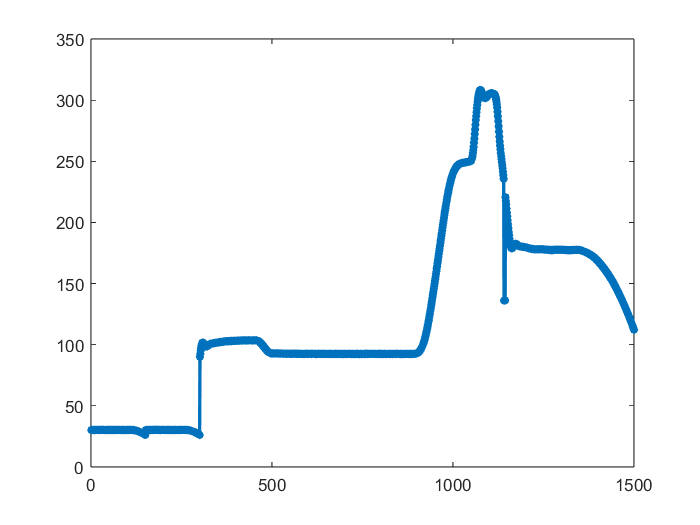

listPosition1 = load("Position(0-4).mat");
listPosition2 = load("Position(5-9).mat");
listPosition = [listPosition1.listPosition listPosition2.listPosition];

listPosition1 = load("PosBottomArm(0-4).mat");
listPosition2 = load("PosBottomArm(5-9).mat");
%listPosition = [listPosition1.listPosBottomArm listPosition2.listPosBottomArm];


%plot original angles
figure,  plot(1:length(listPosition), listPosition, '-o', 'LineWidth', 2, 'MarkerSize', 3);


%process
[speedPerSec, positions] = GetSpeed(listPosition) ;

1141.000000 , 136.186984   
1141.000000 , 136.186984   
1141.000000 , 136.186984   
1141.000000 , 136.186984   
1141.000000 , 136.186984   


#### Plot the processed angle

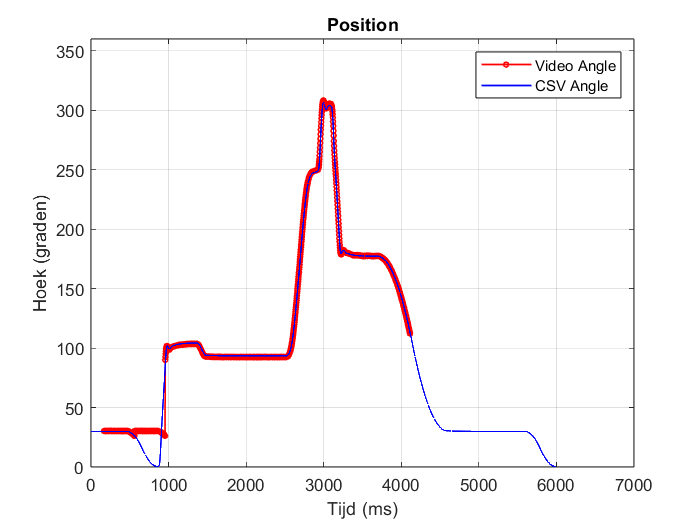

% Frame-rate en tijd per frame in ms
frames_per_second = 380;
tijd_per_frame = 1000 / frames_per_second;  % Tijd per frame in ms (2.6316 ms per frame)
tijden_video_ms = (1:length(listPosition)) * tijd_per_frame;  % Tijd in ms voor elk frame
    

% plot angle + csv angle

% CSV file - Position
data = readmatrix('Dataset encoder 1.csv');  
tijden_csv = 25:24025;  % 25 = begin data, 24025 is ongeveer 1 cyclus
graden_csv = data(tijden_csv, 8);    % 8ste kolom is positie
tijden_csv_ms = data(tijden_csv, 1); % 1e kolom is tijd in ms

tijden_video_ms = tijden_video_ms + 165;

figure, plot(tijden_video_ms, positions, '-or', 'LineWidth', 1, 'MarkerSize', 3);
hold on;
plot(tijden_csv_ms, graden_csv, 'b', 'LineWidth', 1);

% Labels en titel
xlabel('Tijd (ms)');
ylabel('Hoek (graden)');
title('Position');
grid on;
ylim([0, 360]); 
legend('Video Angle', 'CSV Angle');

hold off;

#### Plot the speed

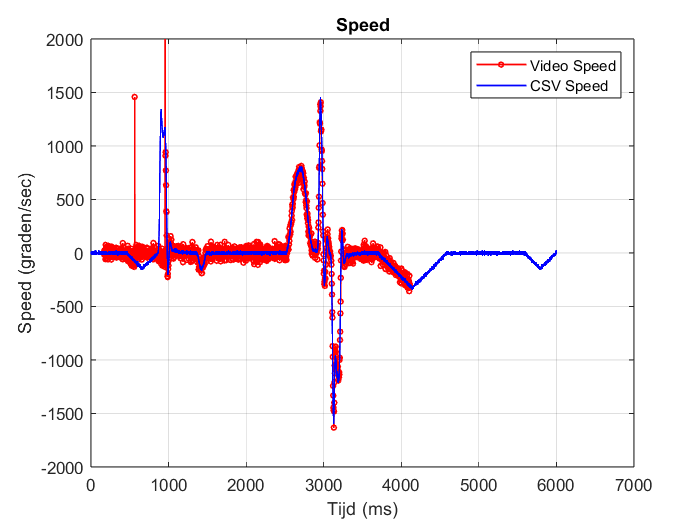


%plot speed + csv speed

% CSV file - Position
data = readmatrix('Dataset encoder 1.csv');  
tijden_csv = 25:24025;  % 25 = begin data, 24025 is ongeveer 1 cyclus
snelheid_csv = data(tijden_csv, 10);    % 10e kolom is positie
tijden_csv_ms = data(tijden_csv, 1); % 1e kolom is tijd in ms

figure, plot(tijden_video_ms, speedPerSec, '-or', 'LineWidth', 1, 'MarkerSize', 3);
hold on;
plot(tijden_csv_ms, snelheid_csv, 'b', 'LineWidth', 1);

% Labels en titel
xlabel('Tijd (ms)');
ylabel('Speed (graden/sec)');
title('Speed');
grid on;
 ylim([-2000, 2000]);
legend('Video Speed', 'CSV Speed');

hold off;